# **Problem 1**

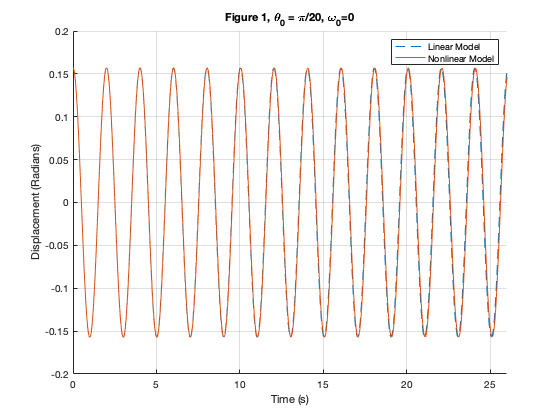

global m l k a g k2
m=2; l=1; k=100; a=0.5; g=9.81; %system parameters
theta01a = pi/20; omega0 = 0; %initial conditions
theta01b = pi/2; %initial conditions

tspan = 0:0.01:26;
icA = [theta01a omega0];
icB = [theta01b omega0];

[t1, ODE1a1] = ode45(@linear,tspan,icA);
[t2, ODE1a2] = ode45(@nonlinear,tspan,icA);
[t3, ODE1b1] = ode45(@linear,tspan,icB);
[t4, ODE1b2] = ode45(@nonlinear,tspan,icB);

figure(1)
hold on
plot(t1, ODE1a1(:,1),'--')
plot(t2, ODE1a2(:,1))
xlim([0 tspan(end)]);
ylabel('Displacement (Radians)')
xlabel('Time (s)')
title('Figure 1, \theta_0 = \pi/20, \omega_0=0')
legend('Linear Model','Nonlinear Model')
grid on
hold off

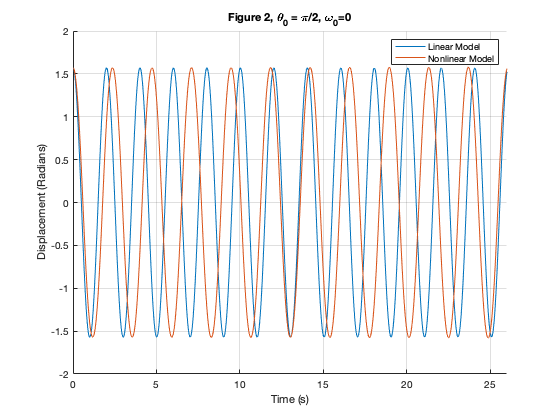


figure(2)
hold on
plot(t3, ODE1b1(:,1))
plot(t4, ODE1b2(:,1))
xlim([0 tspan(end)]);
ylabel('Displacement (Radians)')
xlabel('Time (s)')
title('Figure 2, \theta_0 = \pi/2, \omega_0=0')
legend('Linear Model','Nonlinear Model')
grid on
hold off


periodA = 2.01;
periodB = 2.37;

# **Problem 2**

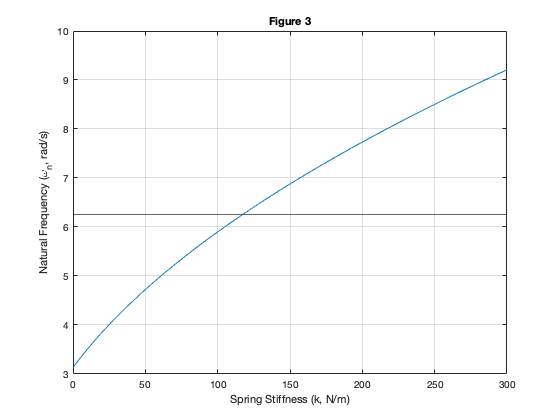

k = 0:0.1:300;
wn = sqrt((g/l) + (k.*a)./(m/l^2));

figure(3)
plot(k,wn);
title('Figure 3')
xlabel('Spring Stiffness (k, N/m)')
ylabel('Natural Frequency (\omega_n, rad/s)')
grid on

wn2 = sqrt(g/l); %derived from linear model in 1a
wn3 = 2 * wn2; %twice the angular velocity
yline(wn3)

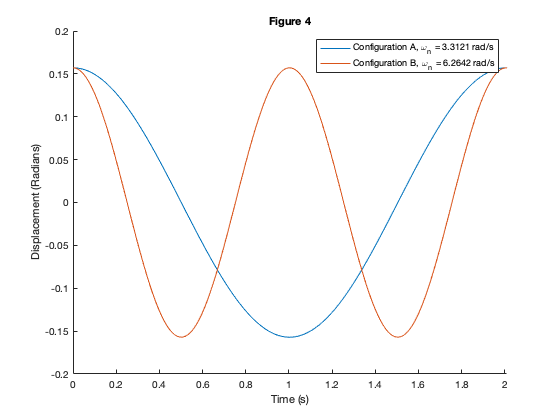


k2 = 117.72; %found graphically
[t5, ODE2b] = ode45(@linear2,tspan,icA);

figure(4)
hold on
plot(t1, ODE1a1(:,1))
plot(t5, ODE2b(:,1))
xlim([0 2.01])
ylabel('Displacement (Radians)')
xlabel('Time (s)')
title('Figure 4')
legend('Configuration A, \omega_n = 3.3121 rad/s', 'Configuration B, \omega_n = 6.2642 rad/s')

# **Problem 3**

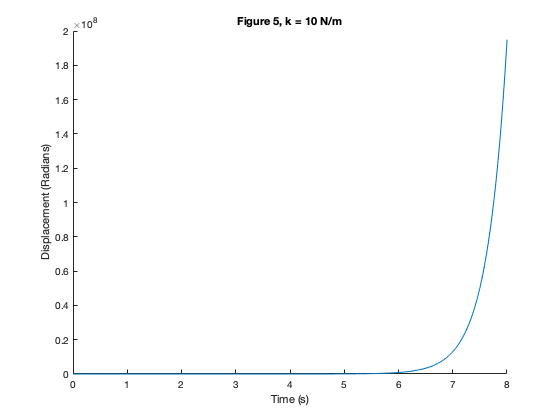

global k3 k4
k3 = 10; k4 = 10^9; %new parameters

[t6, ODE3a] = ode45(@linear3,tspan,icA);
[t7, ODE3b] = ode45(@linear4,tspan,icA);

figure(5)
hold on
plot(t6,ODE3a(:,1))
xlim([0 8])
title('Figure 5, k = 10 N/m')
xlabel('Time (s)')
ylabel('Displacement (Radians)')

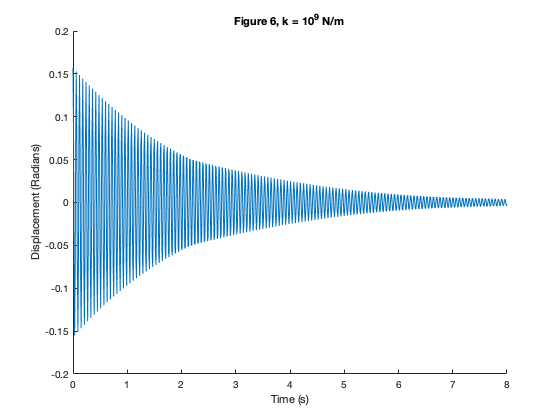


figure(6)
hold on
plot(t7,ODE3b(:,1))
xlim([0 8])
title('Figure 6, k = 10^9 N/m')
xlabel('Time (s)')
ylabel('Displacement (Radians)')

# **Functions**

## **Linear Model Function (Problem 1)**

function thetaDot = linear(t,theta) %system of equations for linear model
global l g 
thetaDot = zeros(2,1);
thetaDot(1) = theta(2);
thetaDot(2) = -(g/l)*theta(1);
end

## Nonlinear Model Function (Problem 1)

function thetaDot = nonlinear(t,theta) %system of equations for nonlinear model
global l g
thetaDot = zeros(2,1);
thetaDot(1) = theta(2);
thetaDot(2) = -(g/l) * sin(theta(1));
end

## Linear Model of Configuration B (Problem 2)

function thetaDot = linear2(t,theta)
global l g k2 m a
thetaDot = zeros(2,1);
thetaDot(1) = theta(2);
thetaDot(2) = -((g/l)+(k2*a)/(m*l^2)) * theta(1);
end

## Linear Model of Configuration C, k = 10 N/m (Problem 3)

function thetaDot = linear3(t,theta)
global k3 a m l g
thetaDot = zeros(2,1);
thetaDot(1) = theta(2);
thetaDot(2) = ((g/l)-(k3*a)/(m*l^2)) * theta(1);
end

## Linear Model of Configuration C, k = 10^9 N/m (Problem 3)

function thetaDot = linear4(t,theta)
global k4 a m l g
thetaDot = zeros(2,1);
thetaDot(1) = theta(2);
thetaDot(2) = ((g/l)-(k4*a)/(m*l^2)) * theta(1);
end